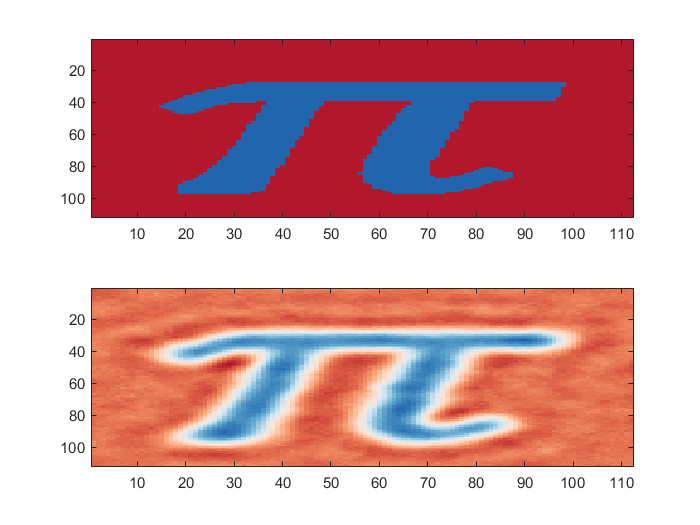

clear
global  txt
beta  = 0.02;
root = 'D:\study\DLpattern\PatternDL\python\data\';
modelName = 'B05_Layers3_white_beta002_imsize112_kernel10_Second';
PatternFInal = readNPY([root, modelName,'\Patterns.npy']);
% PatternPython = readNPY(['D:\study\DLpattern\PatternDL\python\data\Kaggle_Layers2_pink_beta001_imsize112_kernel10_First\PatternsTrained001.npy']);
% Ipython = readNPY([root, modelName,'\Intensity.npy']);
% PmeanPython = readNPY([root, modelName,'\Pmean.npy']);
% CGIpython = readNPY([root, modelName,'\CGI_img.npy']);
% PIpython = readNPY([root, modelName,'\PI.npy']);
img_ori =double( imresize(imread([root,'check_pic\pi.png']),[112,112]) );
imgOriSize = size(img_ori);
if(imgOriSize(3)==3)
    img_ori = rgb2gray(img_ori);
end
% img_ori = readNPY([root, modelName,'\input_image.npy']);

% PatternPython = (PatternPython);
txtSize = size(PatternFInal);
% PatternPython = reshape(PatternPython(1,:,:,:),txtSize(2:end));
img_ori  = reshape(img_ori,txtSize(3:end));
txt = zeros([txtSize(3:4),txtSize(2)]);
for ii = 1:txtSize(2)
    txt(:,:,ii) = PatternFInal(1,ii,:,:);
%     txt(:,:,ii) = a(1,ii,:,:);
    txt(:,:,ii) = txt(:,:,ii) -reshape(PatternFInal(1,1,:,:),[112,112]) ;
%     a = txt(:,:,ii);
%     a = rescale(a, 0 ,255);
%     a(a>55)=a(a>55).*55./ max(max((a)));
%     a = round(rescale(a, 0 ,255));
%     txt(:,:,ii)  = a;
%     imagesc(txt(:,:,ii))
end

[CGIimageMatlab,Imatlab,PmeanMatlab,PImeanMatlab] = generateCGI(img_ori,beta,112,112);

% imagesc(PImeanMatlab-PmeanMatlab.*mean(Imatlab))
% PmeanPython = reshape(PmeanPython,size(PmeanMatlab));
% PIpython = reshape(PIpython,size(PmeanMatlab));
% CGIpython = reshape(CGIpython,[84,84]);

subplot(2,1,1)
imagesc(img_ori)
subplot(2,1,2)
imagesc(CGIimageMatlab)
colormap(othercolor('RdBu6'))